# Natural Resources Management . Final Project

addpath("utils\")

## Part 0. Data pre-processing

file = readmatrix("data\5. Jochenstein.csv");
data_precipitation = file(:,4); % [mm/d]
data_streamflow = file(:,5); % [m3/s]
data_temperature = file(:,6); % °C

### Dataset times

Total dataset total years and years used for training, taking 70% of the dataset

T = 365;
tr_length = 0.70;
years_total = length(file) / T

years_total = 27

years_tr = floor(years_total*tr_length)

years_tr = 18

### Dataset partition 

% Training dataset
x_tr = data_streamflow(1:T*years_tr);
u_tr = [data_precipitation(1:T*years_tr) data_temperature(1:T*years_tr)];
% Validation dataset
x_val = data_streamflow(T*years_tr+1:end);
u_val = [data_precipitation(T*years_tr+1:end) data_temperature(T*years_tr+1:end)];

### Cyclostationary  analysis

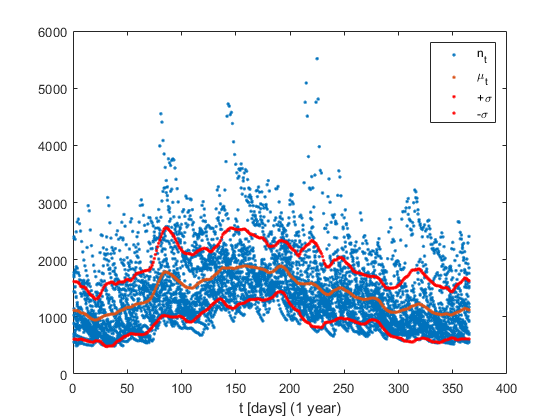

f = 5; 
N_tr = length(x_tr);
tt = repmat([1:T]', N_tr/T, 1);
% Moving Average
[mi, m] = moving_average(x_tr, T, f);
% Moving variance
[ma_var2, s2] = moving_average((x_tr - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);
figure;
plot(tt, [x_tr, m], '.');
xlabel('t [days] (1 year)');
hold on;
% plot([1 : T], mi, 'g', 'LineWidth',.5);
plot(tt, m + s, '.r');
plot(tt, m - s, '.r');
legend('n_t', '\mu_t', '+\sigma', '-\sigma');

% legend('n_t', '\mu_t', '\mu_{cyclo}', '+\sigma', '-\sigma');

### Correlations

#### Streamflow - Precipitations

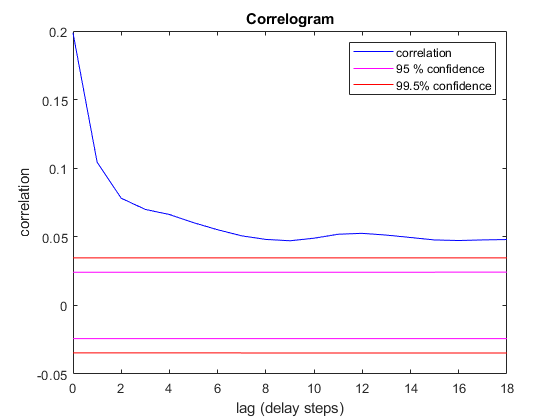

figure; correlogram(x_tr, u_tr(:,1), years_tr)

#### Streamflow - Temperature

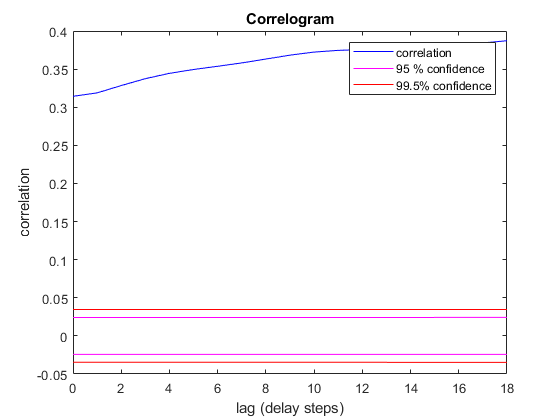

figure; correlogram(x_tr, u_tr(:,2), years_tr)

### Data normalization

f = 5; 
[x_norm, mean_x, sigma_x] = deseasonalize(x_tr, T, f);
[u_norm(:,1), mean_u(:,1), sigma_u(:,1)] = deseasonalize(u_tr(:,1), T, f);
[u_norm(:,2), mean_u(:,2), sigma_u(:,2)] = deseasonalize(u_tr(:,2), T, f);

[x_norm_val, mean_x_val, sigma_x_val] = deseasonalize(x_val, T, f);
[u_val_norm(:,1), mean_u_val(:,1), sigma_u_val(:,1)] = deseasonalize(u_val(:,1), T, f);
[u_val_norm(:,2), mean_u_val(:,2), sigma_u_val(:,2)] = deseasonalize(u_val(:,2), T, f);

### Correlations

#### Streamflow - Precipitations

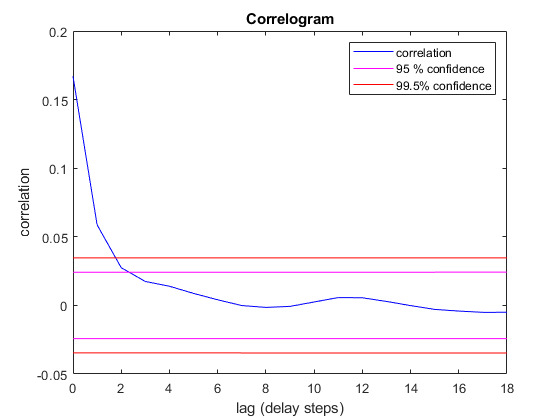

figure; correlogram(x_norm, u_norm(:,1), years_tr)

#### Streamflow - Temperature

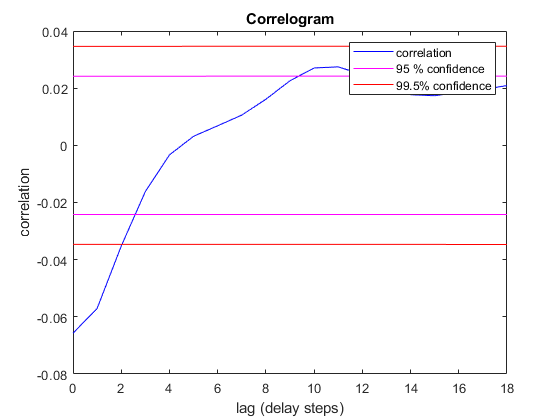

figure; correlogram(x_norm, u_norm(:,2), years_tr)

## Part 1. 1-day ahead forecast model

### Linear models

#### AR (1)

y_ar1 = x_norm(2:end);
M_ar1 = x_norm(1:end-1);
theta_ar1 = M_ar1\y_ar1

theta_ar1 = 0.9697

x_norm_ar1 = [x_norm(1); M_ar1*theta_ar1];
x_ar1 = x_norm_ar1 .* sigma_x + mean_x;

Training R2 index

r2_ar1 = r2_performance(x_tr, x_ar1, mean_x)

r2_ar1 = 0.9446

Validation R2 index

M_ar1_val = x_norm_val(1:end-1);
x_norm_ar1_val = [x_norm_val(1); M_ar1_val*theta_ar1];
x_ar1_val = x_norm_ar1_val .* sigma_x_val + mean_x_val;
r2_ar1_val = r2_performance(x_val, x_ar1_val, mean_x_val)

r2_ar1_val = 0.9247

#### AR (2)

y_ar2 = x_norm(3:end);
M_ar2 = [x_norm(2:end-1), x_norm(1:end-2)];
theta_ar2 = M_ar2\y_ar2

theta_ar2 =     1.6007
   -0.6487


x_norm_ar2 = [x_norm(1:2);  M_ar2*theta_ar2];
x_ar2 = x_norm_ar2 .* sigma_x + mean_x;

Training R2 index

r2_ar2 = r2_performance(x_tr, x_ar2, mean_x)

r2_ar2 = 0.9698

Validation R2 index

M_ar2_val = [x_norm_val(2:end-1), x_norm_val(1:end-2)];
x_norm_ar2_val = [x_norm_val(1:2); M_ar2_val*theta_ar2];
x_ar2_val = x_norm_ar2_val .* sigma_x_val + mean_x_val;
r2_ar2_val = r2_performance(x_val, x_ar2_val, mean_x_val)

r2_ar2_val = 0.9569

#### AR (3)

y_ar3 = x_norm(4:end);
M_ar3 = [x_norm(3:end-1), x_norm(2:end-2), x_norm(1:end-3)];
theta_ar3 = M_ar3\y_ar3

theta_ar3 =     1.9227
   -1.3973
    0.4483


x_norm_ar3 = [x_norm(1:3);  M_ar3*theta_ar3];
x_ar3 = x_norm_ar3 .* sigma_x + mean_x;

Training R2 index

r2_ar3 = r2_performance(x_tr, x_ar3, mean_x)

r2_ar3 = 0.9771

Validation R2 index

M_ar3_val = [x_norm_val(3:end-1), x_norm_val(2:end-2), x_norm_val(1:end-3)];
x_norm_ar3_val = [x_norm_val(1:3); M_ar3_val*theta_ar3];
x_ar3_val = x_norm_ar3_val .* sigma_x_val + mean_x_val;
r2_ar3_val = r2_performance(x_val, x_ar3_val, mean_x_val)

r2_ar3_val = 0.9667

#### AR (4)

y_ar4 = x_norm(5:end);
M_ar4 = [x_norm(4:end-1), x_norm(3:end-2), x_norm(2:end-3), x_norm(1:end-4)];
theta_ar4 = M_ar4\y_ar4

theta_ar4 =     2.0153
   -1.6691
    0.7835
   -0.1591


x_norm_ar4 = [x_norm(1:4);  M_ar4*theta_ar4];
x_ar4 = x_norm_ar4 .* sigma_x + mean_x;

Training R2 index

r2_ar4 = r2_performance(x_tr, x_ar4, mean_x)

r2_ar4 = 0.9781

Validation R2 index

M_ar4_val = [x_norm_val(4:end-1), x_norm_val(3:end-2), x_norm_val(2:end-3), x_norm_val(1:end-4)];
x_norm_ar4_val = [x_norm_val(1:4); M_ar4_val*theta_ar4];
x_ar4_val = x_norm_ar4_val .* sigma_x_val + mean_x_val;
r2_ar4_val = r2_performance(x_val, x_ar4_val, mean_x_val)

r2_ar4_val = 0.9679

#### Proper ARX (1,1)

#### Improper ARX (1,1)

### Nonlinear models

#### Proper ANN

#### Improper ANN

#### CART

### Models comparison

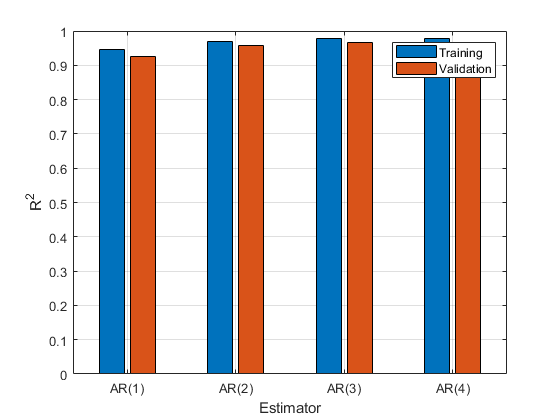

c = categorical({ ...
    'AR(1)', ...
    'AR(2)', ...
    'AR(3)', ...
    'AR(4)', ...
    });
h = bar(c,[ ...
    r2_ar1, r2_ar1_val; ...
    r2_ar2, r2_ar2_val; ...
    r2_ar3, r2_ar3_val; ...
    r2_ar4, r2_ar4_val; ...
    ]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Estimator');ylabel('R^2');
legend()
grid on

## Part 2. Dam sizing impacts